# Ejercicio 1

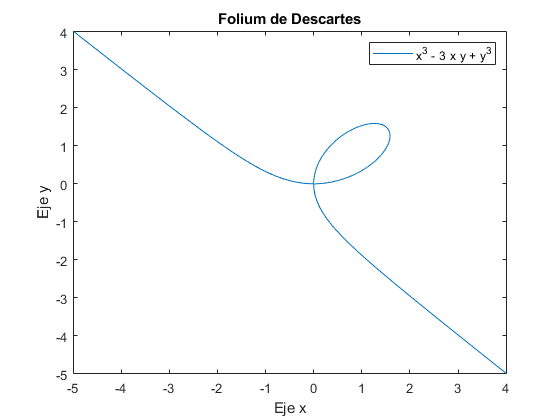

clc; clear
syms x y t
a = 1;
fimplicit(x.^3 + y.^3 - 3 * a * x * y)
legend("-DynamicLegend")
legend("show")
xlabel("Eje x")
ylabel("Eje y")
title("Folium de Descartes")

Las ecuaciones paramétricas dadas por: $y=t\;x\;,\;x\not= 0$ 

son:


$$x=\frac{3\;a\;t}{1+t^3 }$$



$$y=\frac{3\;a\;t^2 }{1+t^3 }$$


Para pasar a polares:

se sabe que :

$x=r\;\cos \;\theta \;,y=r\;\sin \;\theta$, entonces partiendo de la ecuación implícita sabemos que:


$$r^{3\;} \;\cos^3 \;\theta +r^{3\;} \;\sin^3 \;\theta -3\;r^{2\;} \;\cos \;\theta \;\sin \;\theta =0$$


y para:


$$r\;\not= \;0$$


tenemos:


$$r=\frac{3\;\cos \;\theta \;\sin \;\theta }{\cos^3 \;\theta +\sin^3 \;\theta }=\frac{3\;\left(\frac{1}{\cos \;\theta }\right)\frac{\sin \;\theta }{\cos \;\theta }}{1+\frac{\sin^3 \;\theta }{\cos^3 \;\theta }}=\frac{3\;\sec \;\theta \;\tan \;\theta }{1+\tan^3 \;\theta }$$


graficando:

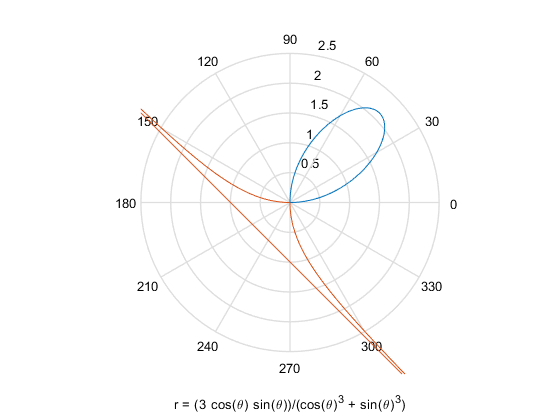

syms theta
rho = (3 * a * cos(theta) * sin(theta)) / (cos(theta)^3 + sin(theta)^3);
ezpolar(rho, [(-pi/6) (pi/2)])
hold on
ezpolar(rho, [(pi/2) (pi)])
hold off

Para la integral del bucle, usamos las ecuaciones paramétricas,  empleando la fórmula de:


$$\frac{1}{2}\oint_{\partial F} \left(x\;\textrm{dy}-y\;\textrm{dx}\right)$$


x = (3 *a * t) / (1 + t^3);
y = (3 * a * t^2) / (1 + t^3);
area = (1 / 2) * int(x * diff(y) - y * diff(x), 0 , inf)

$$area = \frac{3}{2}$$

Para guardar el archivo usar: (*solo funciona si es .m*)

% publish('folium.m','pdf')